# **Κεφάλαιο 2: Μηχανές Διανυσματικής Στήριξης: Η Μη - Γραμμική Περίπτωση**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Support Vector Machines - Η μη-Γραμμική Περίπτωση

### Παράδειγμα 1

- Δημιουργήστε ένα διδιάστατο σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) ως εξής: επιλέξτε $N=150$ σημεία δεδομένων στη διδιάστατη περιοχή $[-5,5]\times[-5,5]$, σύμφωνα με την ομοιόμορφη κατανομή. Αναθέστε κάθε σημείο $x=[x(1),x(2)]^T$ στην κλάση $+1(-1)$ σύμφωνα με τον κανόνα $0.05(x^3(1)+x^2(1)+x(1)+1)>(<)x(2)$. Προφανώς οι δύο κλάσεις δεν είναι γραμμικώς διαχωρίσιμες. Για την ακρίβεια διαχωρίζονται με την καμπύλη της εξίσωσης $0.05(x^3(1)+x^2(1)+x(1)+1) = x(2)$. Να γίνει η γραφική αναπαράσταση των σημείων του $X_1$.

- Σχεδιάστε έναν γραμμικό SVM ταξινομητή χρησιμοποιώντας παραμέτρους $C=2$ και $tol=0.001$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής και μετρήστε τα διανύσματα στήριξης

- Δημιουργήστε έναν μη γραμμικό ταξινομητή SVM με συνάρτηση πυρήνα ακτινωτής βάσης θέτοντας $\sigma=0.1$ και $2$. Χρησιμοποιήστε παραμέτρους $C=2$ και $tol=0.001$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής και μετρήστε τον αριθμό των διανυσμάτων στήριξης. Αποδώστε γραφικά τις περιοχές που ορίζει ο ταξινομητής.

- Να επαναληφθεί το βήμα 3 χρησιμοποιώντας συναρτήσει πολυωνυμικού πυρήνα της μορφής $(x^Ty+\beta)^n$ για $(n,\beta)=(5,0)$ και $(3,1)$ και να εξαχθούν συμπεράσματα

- Σχεδιάστε SVM ταξινομητές χρησιμοποιώντας την συνάρτηση πυρήνα ακτινωτής βάσης με $\sigma=1.5$ και τη συνάρτηση πολυωνυμικού πυρήνα με $n=3,\beta=1$ χρησιμοποιώντας τιμές των παραμέτρων $tol=0.001, C=0.2, 20, 200$

close('all');
clear

format compact
global figt4

l=2;   % Dimensionality
N=150; % Number of vectors

% Generate the training set X1
rand('seed',0)
X1=10*rand(l,N)-5;
for i=1:N
    t=0.05*(X1(1,i)^3+X1(1,i)^2+X1(1,i)+1);
    if(t>X1(2,i))
        y1(i)=1;
    else
        y1(i)=-1;
    end
end

% Generate the test set X2
rand('seed',100)
X2=10*rand(l,N)-5;
for i=1:N
    t=0.05*(X2(1,i)^3+X2(1,i)^2+X2(1,i)+1);
    if(t>X2(2,i))
        y2(i)=1;
    else
        y2(i)=-1;
    end
end

% Plot the training set X1
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bo')
figure(1), axis equal

%%%%%%%%%%%%%%%%%%%%% Linear SVM %%%%%%%%%%%%%%%%%%%%% 
fprintf('\n\n');
figt4=2;

kernel='linear'

kernel = 'linear'

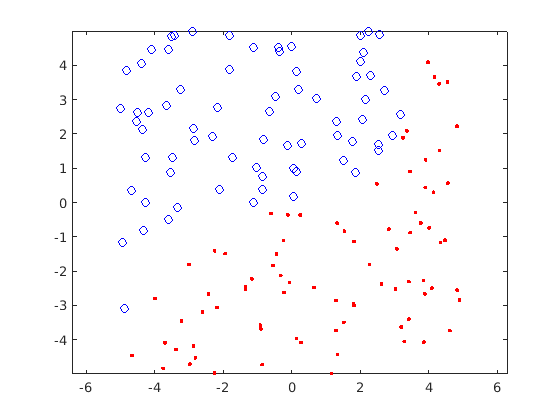

kpar1=0; 
kpar2=0; 
C=2;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b; 
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);


figure(figt4), axis equal

X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Margin
marg=2/sum(w.^2)

marg = 0.7570


% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0.0733


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.0733


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 26



% %%%%%%%%%%%%%%%%%%% RBF kernel%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figt4=3;
fprintf('\n\n');

kernel='rbf'

kernel = 'rbf'

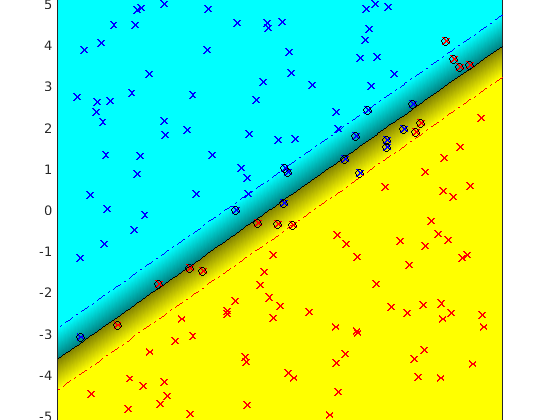

kpar1=0.1; 
kpar2=0; 
C=2;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b;  
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);


figure(figt4), axis equal

X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.3267


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 150


% %%%%%%%%%%%%%%% POLYNOMIAL KERNEL %%%%%%%%%%%%%%%%%%%%%%%
figt4=4;
fprintf('\n\n');

kernel='poly'

kernel = 'poly'

kpar1=0; 
kpar2=5; 
C=2;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

The algorithm has not converged. This may be due to:
 (a) the maximum number of iterations has been reached and convergence has not, yet, been achieved or 
 (b) the chosen values for the hyperparameters (C as well as the parameters that define the kernel function) 
 can not lead to a solution. 


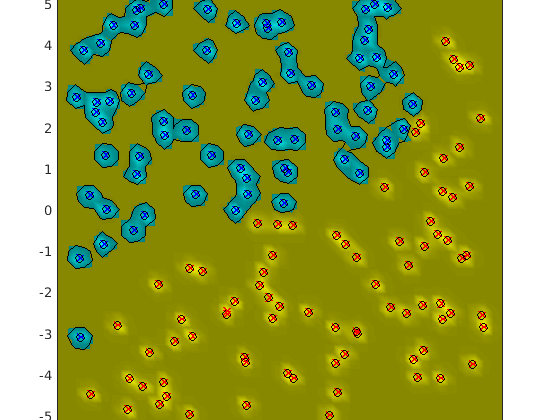


mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b;  
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);

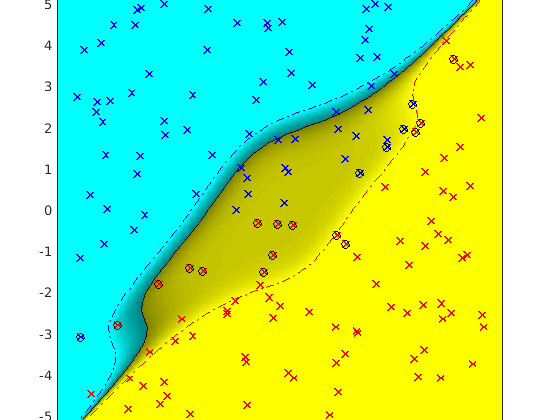


figure(figt4), axis equal


X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0.1333


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.0733


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 35

### Παράδειγμα 2

- Δημιουργήστε ένα διδιάστατο σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) ως εξής: θεωρήστε τα εννέα τετράγωνα $[i,i+1] \times[j,j+1],i=0,1,2, j=0,1,2$ και επιλέξτε $30$ σημεία από κάθε τετράγωνο με τυχαίο τρόπο σύμφωνα με την ομοιόμορφη κατανομή. Τα σημεία που προέρχονται από τετράγωνα όπου $i+j$ είναι άρτιος (περιττός) ανατίθενται στην κλάση $1(-1)$ (η κατανομή των σημείων στον χώρο θυμίζει σκακιέρα με μαύρα και λευκά τετράγωνα). Να σχεδιαστεί το σύνολο των δεδομένων και να δημιουργηθεί ένα επιπλέον σύνολο δεδομένων $X_2$ (σύνολο δοκιμής) ακολουθώντας την συνταγή του $X_1$ (όπως και στο προηγούμενο παράδειγμα να αρχικοποιήσετε την συνάρτηση rand με $0$ για το $X_1$ και $100$ για το $X_2$).

- Δημιουργήστε έναν γραμμικό SVM ταξινομητή χρησιμοποιώντας τιμές παραμέτρων $C=200, tol=0.001$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής και μετρήστε τα διανύσματα στήριξης

- Δημιουργήστε μη γραμμικούς SVM ταξινομητές με συναρτήσεις πυρήνα ακτινωτής βάσης εφαρμόζοντας τον προηγούμενο αλγόριθμο για $C=0.2, 2, 20, 200, 2000, 20000$. Να τεθεί $\sigma=1, 1.5, 2.5$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής και μετρήστε τα διανύσματα στήριξης.

- Να επαναληφθεί το προηγούμενο βήμα για πολυωνυμική συνάρτηση πυρήναμ χρησιμοποιώντας $n=3,5$ και $\beta=1$.

- Για όλες τις παραπάνω περιπτώσεις να εξαχθούν συμπεράσματα.

close('all');
clear

format compact
global figt4

% 1. Generate X1
l=2; %Dimensionality
poi_per_square=30; %Points per square
N=9*poi_per_square; %Total no. of points
rand('seed',0)
X1=[];
y1=[];
for i=0:2
    for j=0:2
        X1=[X1 rand(l,poi_per_square)+...
            [i j]'*ones(1,poi_per_square)];
        if(mod(i+j,2)==0)
            y1=[y1 ones(1,poi_per_square)];
        else
            y1=[y1 -ones(1,poi_per_square)];
        end
    end
end

% Plot X1
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bo')
figure(1), axis equal

% Generate X2
rand('seed',100)
X2=[];
y2=[];
for i=0:2
    for j=0:2
        X2=[X2 rand(l,poi_per_square)+...
            [i j]'*ones(1,poi_per_square)];
        if(mod(i+j,2)==0)
            y2=[y2 ones(1,poi_per_square)];
        else
            y2=[y2 -ones(1,poi_per_square)];
        end
    end
end

%%%%%%%%%%%%%%%%%%%%% Linear SVM %%%%%%%%%%%%%%%%%%%%% 
fprintf('\n\n');
figt4=2;

kernel='linear'

kernel = 'linear'

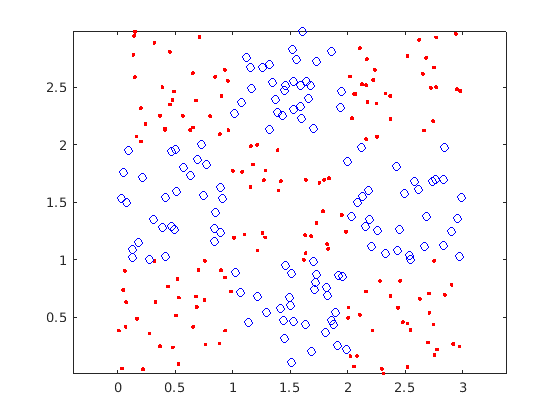

kpar1=0; 
kpar2=0; 
C=200;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b; 
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);


figure(figt4), axis equal

X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Margin
marg=2/sum(w.^2)

marg = 6.8765e+07


% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0.4444


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.4444


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 262



% %%%%%%%%%%%%%%%%%%% RBF kernel%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figt4=3;
fprintf('\n\n');

kernel='rbf'

kernel = 'rbf'

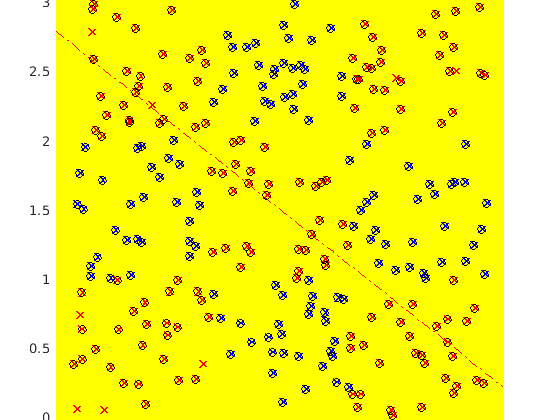

kpar1=0.1; 
kpar2=0; 
C=2000;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b;  
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);


figure(figt4), axis equal

X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.1000


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 216


% %%%%%%%%%%%%%%% POLYNOMIAL KERNEL %%%%%%%%%%%%%%%%%%%%%%%
figt4=4;
fprintf('\n\n');

kernel='poly'

kernel = 'poly'

kpar1=3; 
kpar2=1; 
C=0.2;
tol=0.001;
steps=100000;
eps=10^(-10);
method=1;
[alpha, b, w, evals, stp, glob] = SMO2(X1', y1', kernel, kpar1, kpar2, C, tol, steps, eps, method);

The algorithm has not converged. This may be due to:
 (a) the maximum number of iterations has been reached and convergence has not, yet, been achieved or 
 (b) the chosen values for the hyperparameters (C as well as the parameters that define the kernel function) 
 can not lead to a solution. 


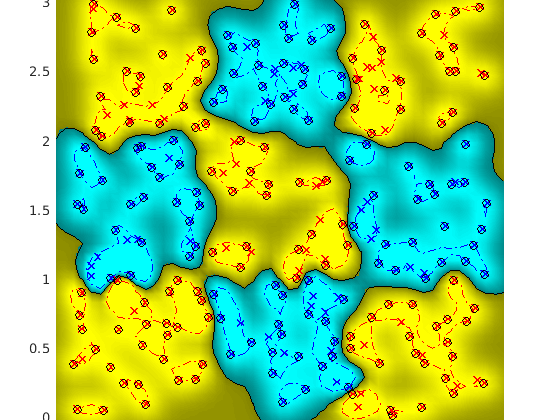


mag=0.1;
xaxis=1;
yaxis=2;
input = zeros(1,size(X1',2));
bias=-b;  
aspect=0;
svcplot_book(X1',y1',kernel,kpar1,kpar2,alpha,bias,aspect,mag,xaxis,yaxis,input);

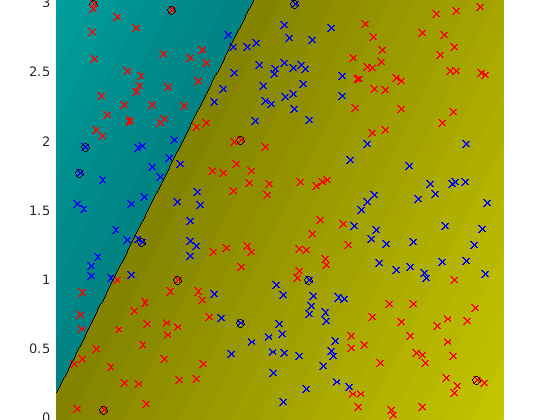


figure(figt4), axis equal


X_sup=X1(:,alpha'~=0);
alpha_sup=alpha(alpha~=0)';
y_sup=y1(alpha~=0);

% Classification of the training set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X1(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_train(i)=1;
    else
        out_train(i)=-1;
    end
end

% Classification of the test set
for i=1:N
    t=sum((alpha_sup.*y_sup).*CalcKernel(X_sup',X2(:,i)',kernel,kpar1,kpar2)')-b;
    if(t>0)
        out_test(i)=1;
    else
        out_test(i)=-1;
    end
end

% Computing the training error
Pe_train=sum(out_train.*y1<0)/length(y1)

Pe_train = 0.4852


% Computing the test error
Pe_test=sum(out_test.*y2<0)/length(y2)

Pe_test = 0.5111


%Counting the number of support vectors
sup_vec=sum(alpha>0)

sup_vec = 12